## **Creating the Learning Factory Environment**

## **Creating the Learning Factory Environment**

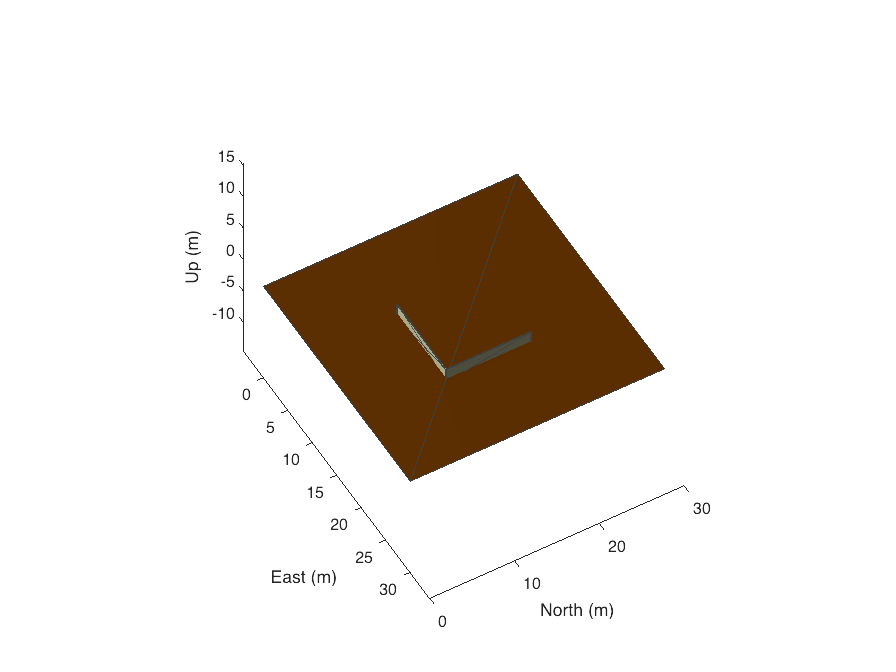

envc = EnvironmentConstants();
[obstacles, scenario, gridSize] = envc.createRobotScenerioEnvironment1();
show3D(scenario);
lightangle(-45,30);
view(60,50);

## Load the agent and create the simulink things

contents = load("experiments_comparison_points/experiment_1_points.mat", "points");
importantCoordinates = contents.points;

## Creating the variables for statistics

numTrials = 100;

numFailures = zeros(numTrials,3);
runTimes = zeros(numTrials,1);
numDeadlocks = zeros(numTrials,1);
numCollisions = zeros(numTrials,1);

distancesTravelled = zeros(numTrials,2);
safetyScores = zeros(numTrials,2);
smoothnessScores = zeros(numTrials,2);

## Create the tasks

for trial=1:numTrials
    %step 1
    rng(trial)
    selected_indices = randperm(length(importantCoordinates),6);
    locations = importantCoordinates(selected_indices,:);
    %format the input string

    stringInput = embedJSON([locations(1,:); locations(4,:)],[locations(2,:); locations(5,:)], [locations(3,:); locations(6,:)],[locations(1,:); locations(4,:)], [1; 2]);
    tic
    taskControlAgent = TaskControlAgent(gridSize, obstacles);
    reservedRoutes = taskControlAgent.executeControl(stringInput, taskControlAgent.PRIORITISED);
    toc

    taskControlAgent.tasks.startCoordinates

    runTimes(trial) = toc;

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% ANALYSE THE ROUTES %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    [maxElements, longestIdx] = max(cellfun(@numel, reservedRoutes));
    numRows = maxElements/2;
    [minElements, shortestIdx] = min(cellfun(@numel, reservedRoutes));
    
    waypoints = {};
    for rIndex=1:length(reservedRoutes)
        thisRoute = reservedRoutes{rIndex};
        currentLength = size(thisRoute,1);
        if currentLength < numRows
            %if the current route is shorter than the longest one then repeat
            %the end to the right length
            temp = zeros(numRows-currentLength,2);
            temp = temp+thisRoute(end,:);
            reservedRoutes{rIndex} = [thisRoute; temp];
        end
        %adjust the coordinates correctly
        temp = zeros(length(reservedRoutes{rIndex}), 2);
        for rIndex2=1:numRows
            currentCoords = reservedRoutes{rIndex}(rIndex2,:);
            temp(rIndex2,:) = [currentCoords(1)-0.5, currentCoords(2)-0.5]; 
        end
        waypoints{rIndex} = temp;
    end
    route1 = waypoints{1};
    route2 = waypoints{2};
    
    %Calculate the Distance Travelled
    travelDistance1 = distanceTravelled(route1);
    travelDistance2 = distanceTravelled(route2);

    %Calculate the Number of Collisions
    totalLength = size(reservedRoutes{longestIdx},1);
    collisions = 0;
    for lIndex=1:totalLength 
        amr1loc = route1(lIndex,:);
        amr2loc = route2(lIndex,:);
    
        locations = [amr1loc; amr2loc];
        collisions = collisions + checkCollisions(locations);
    end

    %Calculate the Number of Deadlocks
    routes = {route1, route2};
    deadlocks = checkDeadlocks(route1, route2);
    
    
    disp("check")
    numFailures(trial, :)
    deadlocks
    collisions
    disp("__________")

    failures = [0 0 0];
    numFailures(trial,:) = failures;
    numDeadlocks(trial) = deadlocks;
    numCollisions(trial) = collisions;
    
    distancesTravelled(trial,:) = [travelDistance1 travelDistance2];
    smoothnessScores(trial,:) = calculateSmoothnessScores({route1, route2});
    safetyScores(trial,:) = calculateSafetyScores({route1, route2});
end

Elapsed time is 2.563767 seconds.


ans =      9    17


ans =     13    28


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.820337 seconds.


ans =     29    15


ans =     25    28


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.035288 seconds.


ans =     19     3


ans =     29    15


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.191098 seconds.


ans =     26    29


ans =      9    17


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.154500 seconds.


ans =      9    17


ans =     13    28


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.792815 seconds.


ans =     25     5


ans =     20     2


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.778513 seconds.


ans =     25     5


ans =     26    29


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.000863 seconds.


ans =     25     5


ans =     19     3


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.330652 seconds.


ans =     29    15


ans =     25    28


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.909610 seconds.


ans =      9    17


ans =     29    29


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.438949 seconds.


ans =     29    29


ans =     24    29


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.794487 seconds.


ans =      4    28


ans =     25     5


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.821266 seconds.


ans =     26    29


ans =     24    29


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.668316 seconds.


ans =     24    29


ans =     25     5


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.122011 seconds.


ans =     26    29


ans =      5    30


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.933316 seconds.


ans =     25    28


ans =     25     5


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.040595 seconds.


ans =     25     5


ans =     29    29


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.131037 seconds.


ans = 1×2
     4    28


ans = 1×2
    29    29


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.946920 seconds.


ans = 1×2
    25    28


ans = 1×2
     5    30


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.315786 seconds.


ans = 1×2
    29    29


ans = 1×2
    24    29


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.858137 seconds.


ans = 1×2
    25    28


ans = 1×2
    29    29


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.616202 seconds.


ans = 1×2
    19     3


ans = 1×2
    29    29


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.214809 seconds.


ans = 1×2
     5    30


ans = 1×2
    29    29


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.313145 seconds.


ans = 1×2
    20     2


ans = 1×2
    24    29


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.667485 seconds.


ans = 1×2
    13    28


ans = 1×2
    29    15


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.331021 seconds.


ans = 1×2
    25     5


ans = 1×2
    29    15


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.576467 seconds.


ans = 1×2
     9    17


ans = 1×2
    25    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.322050 seconds.


ans = 1×2
     5    30


ans = 1×2
    20     2


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.835729 seconds.


ans = 1×2
    29    29


ans = 1×2
    20     2


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.455193 seconds.


ans = 1×2
    25     5


ans = 1×2
     4    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.182480 seconds.


ans = 1×2
     9    17


ans = 1×2
    25    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.261719 seconds.


ans = 1×2
     9    17


ans = 1×2
     5    30


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.270943 seconds.


ans = 1×2
    25    28


ans = 1×2
     4    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.780310 seconds.


ans = 1×2
    29    29


ans = 1×2
    19     3


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.544500 seconds.


ans = 1×2
    29    15


ans = 1×2
    25    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.889178 seconds.


ans = 1×2
    13    28


ans = 1×2
     5    30


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.524794 seconds.


ans = 1×2
    29    29


ans = 1×2
    29    15


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.132212 seconds.


ans = 1×2
    25     5


ans = 1×2
    25    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.066154 seconds.


ans = 1×2
    25     5


ans = 1×2
    24    29


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.108829 seconds.


ans = 1×2
    25    28


ans = 1×2
     9    17


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.444323 seconds.


ans = 1×2
    20     2


ans = 1×2
    29    29


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.143378 seconds.


ans = 1×2
     9    17


ans = 1×2
     5    30


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.755939 seconds.


ans = 1×2
    25    28


ans = 1×2
    13    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.721666 seconds.


ans = 1×2
    29    15


ans = 1×2
     5    30


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.831760 seconds.


ans = 1×2
    29    15


ans = 1×2
     5    30


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.511567 seconds.


ans = 1×2
     5    30


ans = 1×2
    29    29


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.844336 seconds.


ans = 1×2
    24    29


ans = 1×2
    25     5


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.174993 seconds.


ans = 1×2
    24    29


ans = 1×2
    25     5


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.976277 seconds.


ans = 1×2
    29    15


ans = 1×2
    24    29


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.332138 seconds.


ans = 1×2
    13    28


ans = 1×2
    25    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.445514 seconds.


ans = 1×2
    13    28


ans = 1×2
     9    17


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.734453 seconds.


ans = 1×2
    29    29


ans = 1×2
    26    29


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.860603 seconds.


ans = 1×2
    20     2


ans = 1×2
    13    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.968436 seconds.


ans = 1×2
     4    28


ans = 1×2
    25    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.895067 seconds.


ans = 1×2
    25    28


ans = 1×2
    24    29


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.500767 seconds.


ans = 1×2
    20     2


ans = 1×2
    25     5


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.584171 seconds.


ans = 1×2
     9    17


ans = 1×2
    25    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.280058 seconds.


ans = 1×2
     5    30


ans = 1×2
    24    29


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.203598 seconds.


ans = 1×2
     9    17


ans = 1×2
     5    30


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.436905 seconds.


ans = 1×2
     9    17


ans = 1×2
     5    30


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.515492 seconds.


ans = 1×2
    20     2


ans = 1×2
    19     3


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.593077 seconds.


ans = 1×2
    25    28


ans = 1×2
    13    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.542267 seconds.


ans = 1×2
    25     5


ans = 1×2
     9    17


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.236174 seconds.


ans = 1×2
    25     5


ans = 1×2
     5    30


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.900216 seconds.


ans = 1×2
    25     5


ans = 1×2
    25    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.674989 seconds.


ans = 1×2
     4    28


ans = 1×2
    13    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.277352 seconds.


ans = 1×2
    29    29


ans = 1×2
     9    17


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.709677 seconds.


ans = 1×2
    25    28


ans = 1×2
    26    29


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.598372 seconds.


ans = 1×2
     4    28


ans = 1×2
    20     2


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.352962 seconds.


ans = 1×2
    20     2


ans = 1×2
     9    17


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.253827 seconds.


ans = 1×2
    20     2


ans = 1×2
    26    29


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.203080 seconds.


ans = 1×2
     9    17


ans = 1×2
    25    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.918802 seconds.


ans = 1×2
    13    28


ans = 1×2
     9    17


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.966750 seconds.


ans = 1×2
    25    28


ans = 1×2
     9    17


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 4.034842 seconds.


ans = 1×2
    29    15


ans = 1×2
    20     2


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.294979 seconds.


ans = 1×2
    25    28


ans = 1×2
    29    15


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.688244 seconds.


ans = 1×2
     9    17


ans = 1×2
    20     2


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.630896 seconds.


ans = 1×2
    25     5


ans = 1×2
     9    17


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.237301 seconds.


ans = 1×2
    24    29


ans = 1×2
    26    29


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.711367 seconds.


ans = 1×2
    25     5


ans = 1×2
     4    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.764373 seconds.


ans = 1×2
    29    29


ans = 1×2
    25    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.233939 seconds.


ans = 1×2
    19     3


ans = 1×2
    25    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.576740 seconds.


ans = 1×2
    25     5


ans = 1×2
     5    30


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.190324 seconds.


ans = 1×2
    13    28


ans = 1×2
    25     5


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.909717 seconds.


ans = 1×2
    26    29


ans = 1×2
     9    17


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.724243 seconds.


ans = 1×2
     5    30


ans = 1×2
     4    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.721888 seconds.


ans = 1×2
     4    28


ans = 1×2
    29    15


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.020083 seconds.


ans = 1×2
     9    17


ans = 1×2
     5    30


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.053008 seconds.


ans = 1×2
    29    29


ans = 1×2
     4    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.718569 seconds.


ans = 1×2
     5    30


ans = 1×2
    25    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.727616 seconds.


ans = 1×2
    25    28


ans = 1×2
    19     3


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.616892 seconds.


ans = 1×2
     5    30


ans = 1×2
    25     5


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.828996 seconds.


ans = 1×2
    29    29


ans = 1×2
    24    29


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.050065 seconds.


ans = 1×2
    26    29


ans = 1×2
     4    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.201187 seconds.


ans = 1×2
    25     5


ans = 1×2
    24    29


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.390477 seconds.


ans = 1×2
    24    29


ans = 1×2
     5    30


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.508275 seconds.


ans = 1×2
    26    29


ans = 1×2
    19     3


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.524431 seconds.


ans = 1×2
     5    30


ans = 1×2
    29    29


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.947059 seconds.


ans = 1×2
    29    15


ans = 1×2
    26    29


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.242580 seconds.


ans = 1×2
    26    29


ans = 1×2
     4    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________



%Run Times
runTimes

runTimes = 100×1
    2.6034
    2.8314
    3.0426
    3.2131
    2.1640
    3.8037
    2.7855
    3.0368
    3.3388
    3.9431


numFailures

numFailures = 100×3
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


numDeadlocks

numDeadlocks = 100×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


numCollisions

numCollisions = 100×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


distancesTravelled

distancesTravelled = 100×2
    82    46
    76    64
    64    76
    66    84
    72    42
    74    94
    80    48
    58    98
   102    78
    86   104


smoothnessScores

smoothnessScores = 100×2
    9.4248    6.2832
    9.4248   12.5664
   10.9956   14.1372
   12.5664   26.7035
   10.9956    3.1416
   12.5664   12.5664
   12.5664    6.2832
    9.4248   14.1372
   15.7080    6.2832
   18.8496   12.5664


safetyScores

safetyScores = 100×2
     2     2
     8     8
     2     2
     2     2
     0     0
     0     0
    16    16
     1     1
     3     3
     9     9



save('experiments_comparison_results/experiment_1_new_prioritised_ga.mat','runTimes','numFailures','numDeadlocks','numCollisions','distancesTravelled','smoothnessScores','safetyScores');
